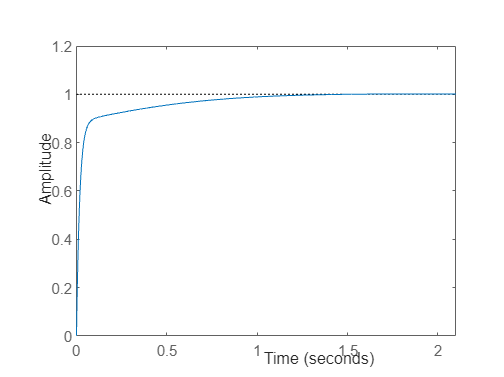

% The goal is to design a PID for a simple system

% https://ctms.engin.umich.edu/CTMS/index.php?example=Introduction&section=ControlPID

% tf between input force F(s) and output displacement X(s)
m = 1; % kg
b = 10; % Ns/m
k = 20; % N/m

s = tf('s');
G = 1 / (m*s^2 + b*s +k); % plant transfer function

%step(G) % open loop step response

% Define PID controller parameters
Kp = 200;
Ki = 300;
Kd = 50;
C = pid(Kp, Ki, Kd);
C = tf(C);

T = feedback(C*G, 1); % (C*G / (C*G +1))

t = 0:0.001:2.1;
step(T,t)

hold on


## Compare Simulink results with MATLAB results

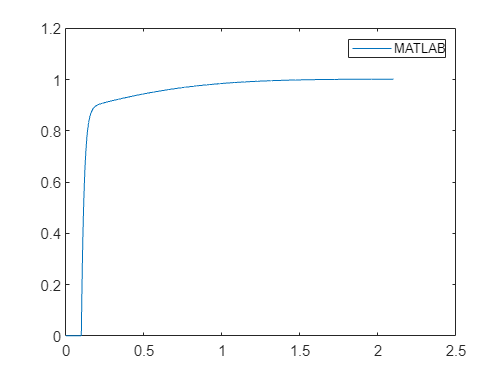

% Simulink parameters
timeInterval = 5e-5;
sampleTime = 1e-3;
stopTime = 2.1;

simout = sim("PIDcontroller.slx");

error = simout.error.Data'; % e(t)
input = simout.input.Data'; % u(t)
y = simout.y.Data; % y(t)

plot(times, y)
legend("MATLAB", "Simulink (0.1 s shifted")

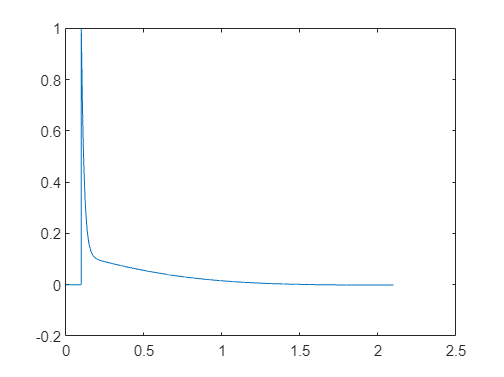

hold off

times = simout.error.Time;
numTimesteps = numel(times);

plot(times,error) 


% discontinuity at step is causing a problem, and how does (0,0)s at the
% beginning helps anyways



% Now need to do downsampling
internalDownsampled = sampleTime / timeInterval

internalDownsampled = 20

timeStepsDownsampled = 1:internalDownsampled:numTimesteps;
errorDownSampled = error(:, timeStepsDownsampled);
inputDownSampled = input(:, timeStepsDownsampled);


% discontinuity at step is causing a problem, and how does (0,0)s at the
% beginning helps anyways
nonzeroIdx = find( errorDownSampled ~= 0, 1)

nonzeroIdx = 101

errorDownSampled = errorDownSampled(:, nonzeroIdx:end);
inputDownSampled = inputDownSampled(:, nonzeroIdx:end);

% Now do train/val/test split


% We could skip that just for now
Xtrain = errorDownSampled; % predictors
Ttrain = inputDownSampled; % targets

## Let's try to prepare data for Feedforward NN here

pastPoints = 3;
numPredictors = length(errorDownSampled);
% So predictors would be like 
% X(3) = [x(1), x(2), x(3)] --> y(3) = y(3)
% X(4) = [x(2), x(3), x(4)] --> y(4) = y(4)
e = errorDownSampled;
X = zeros(numPredictors, pastPoints);

for i = pastPoints:numPredictors
    for j = 1:pastPoints
        %X(i) = [e(i-2), e(i-1), e(i)];
        X(i,j) = e(i - pastPoints + j);
    end
end





## Define the network architecture

numHiddenUnits = 100;

numFeatures = 1; % just error which is 1D as there are no states
numResponses = 1; % again 1D output - just e(t)

layers = [
    sequenceInputLayer(numFeatures,Normalization="rescale-zero-one")
    lstmLayer(numHiddenUnits, "OutputMode","sequence")
    fullyConnectedLayer(numResponses)
    regressionLayer];

## Training

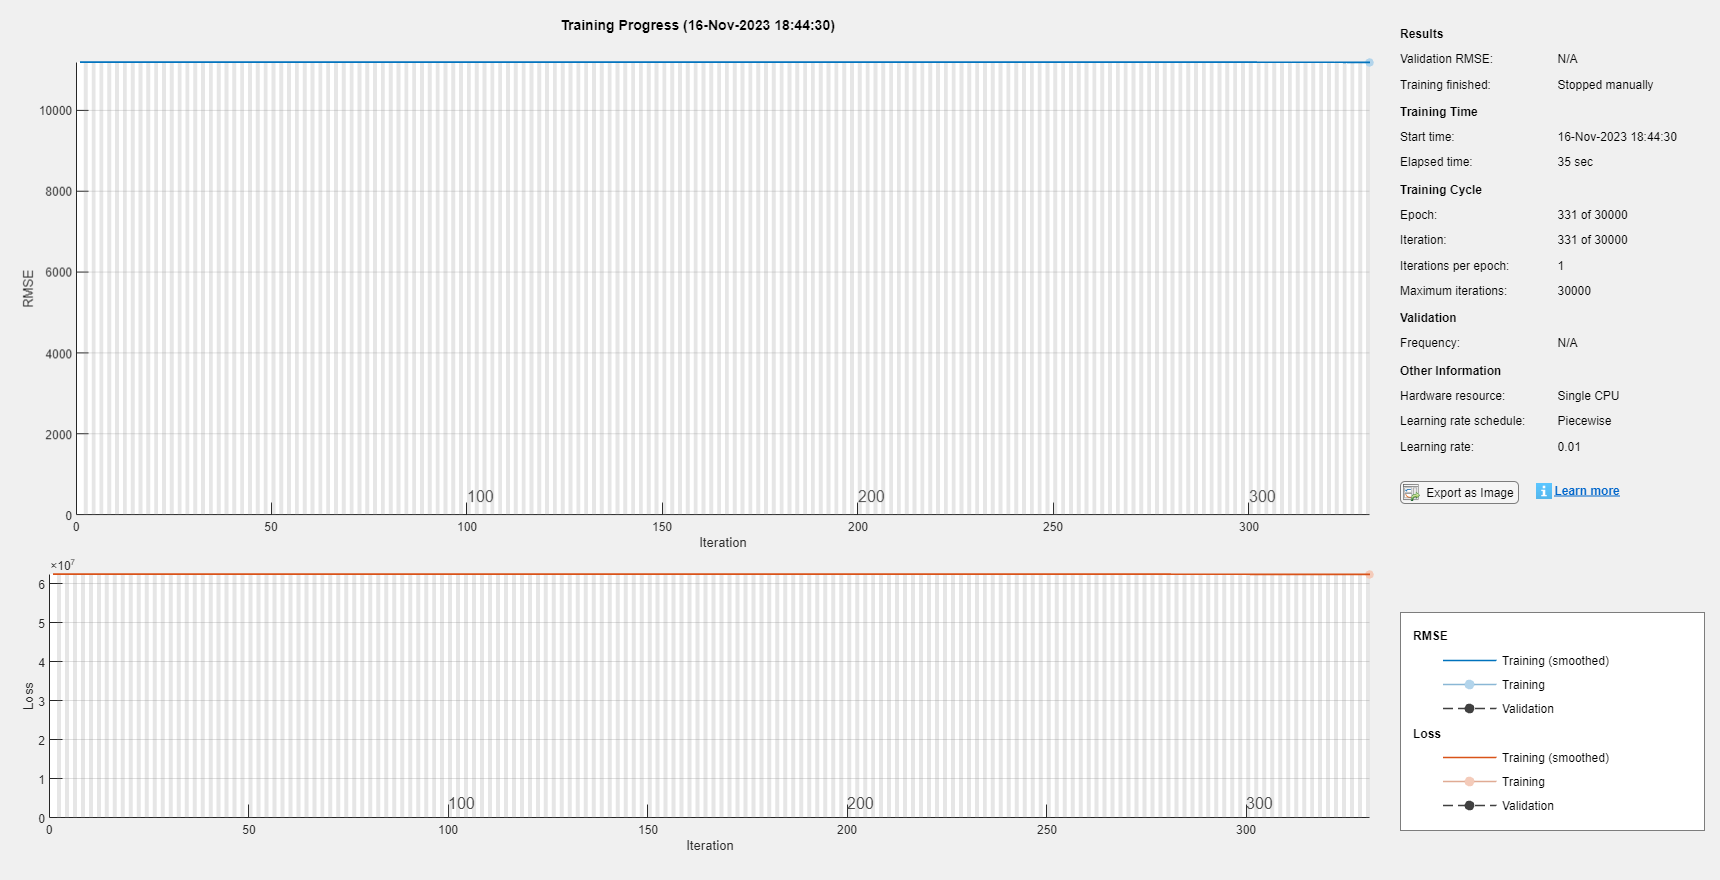

net =   SeriesNetwork with properties:

         Layers: [4×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


info = struct with fields:
              TrainingLoss: [62530116 62530088 62530048 62530060 62530028 62529996 62529956 62529924 62529892 62529856 62529820 62529772 62529724 62529684 62529628 62529568 62529508 62529444 62529376 62529308 62529228 62529128 62529040 … ] (1×331 double)
              TrainingRMSE: [1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 1.1183e+04 … ] (1×331 double)
             BaseLearnRate: [0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 0.0100 … ] (1×331 double)
    OutputNetworkIteration: 331


options = trainingOptions("adam", ...
    MaxEpochs=3e4, ...
    GradientThreshold=1, ...
    InitialLearnRate=1e-2, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropPeriod=1e4, ...
    LearnRateDropFactor=0.6, ...
    Verbose=0, ...
    Plots="training-progress");

[net, info] = trainNetwork(Xtrain, Ttrain, layers, options)